# Sandbox

UWCC Structural Analysis: Heerod Sahraei

Run test scripts in here after running Main.mlx

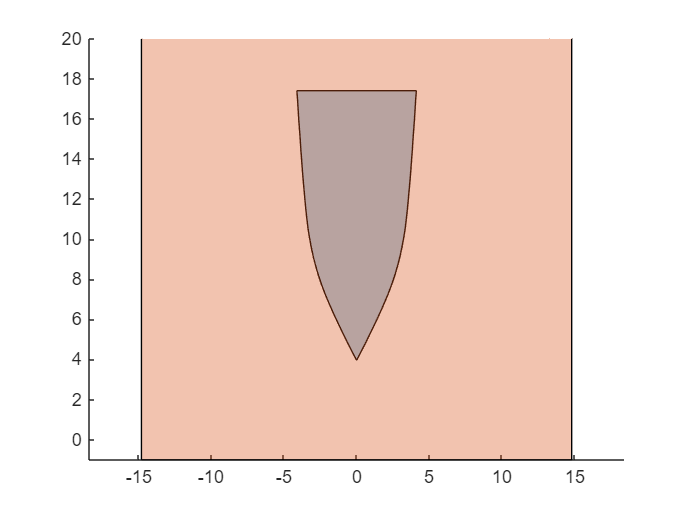

index = 4;
xPos = xUnique(index);
waterline_guess = 11.7+ zmin_all;
trim_guess = -0.1;
waterline_guess = -5.48; trim_guess = -1.3376;
warning('off', 'all');
shape = internalShapes(index);
box = waterbox(waterline_guess + tan(trim_guess) * xPos, 1);
clf;
hold on;
ylim([-1 20]);
xlim([-zmax_all - 1 zmax_all + 1]);
plot(shape);
plot(box);
hold off;

% polyshape is weird asf and doesnt like when you try to transform it 3d.
% have to use patch and some weird Vertices bs
% hold on;
% view(3);
% for i = 1:numel(xUnique)
%     shape = internalShapes(i);
%     positions = shape.Vertices;
%     positions(:,3) = xUnique(i);
%     patch(positions(:,1),positions(:,2),positions(:,3));
%     axis vis3d
% end
% hold off;

### Set Desired Freeboard (in)

freeboard = 0;
draft_ideal = zmax_all - freeboard;

### Calculate Necessary Load (lbs)

weightInitial = 400;
netforcemomentfrompaddlers = @(weight) netforcemoment([freeboard; 0], buoyantdist, ... 
    selfWeightInterp,xInterp,xUnique, [0; -weight]);

function val = optimizationfreeboard(weight,f) 
    result = f(weight);
    val = result(1)^2;
end

fun = @(weight) optimizationfreeboard(weight,netforcemomentfrompaddlers);

[weightIdeal, resultant] = fminsearch(fun,weightInitial,optimset('PlotFcns',@optimplotfval));
close
disp(weightIdeal);

 -307.5032



disp(resultant);

   2.4840e-10

